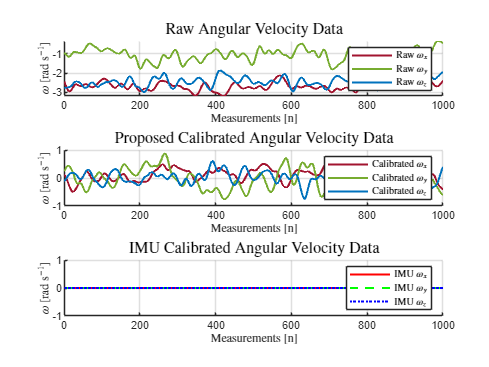

% Read raw and calibrated linear acceleration data
set(0,'defaulttextinterpreter','latex')
rawGyro = dlmread('BNO085_gyro_data_raw.txt', '\t'); %#ok<DLMRD>
calGyro = dlmread('BNO085_gyro_data_cal.txt', '\t'); %#ok<DLMRD>
imuGyro = dlmread('BNO085_gyro_data_imu.txt', '\t'); %#ok<DLMRD>
target_gyro = zeros(length(rawGyro), 3);
% Set the moving average window size
windowSize = 40;
% Apply moving average filter to each column separately
smoothedGyroX = smoothdata(rawGyro(:,1), 'gaussian', windowSize);
smoothedGyroY = smoothdata(rawGyro(:,2), 'gaussian', windowSize);
smoothedGyroZ = smoothdata(rawGyro(:,3), 'gaussian', windowSize);
cal_smoothedGyroX = smoothdata(calGyro(:,1), 'gaussian', windowSize);
cal_smoothedGyroY = smoothdata(calGyro(:,2), 'gaussian', windowSize);
cal_smoothedGyroZ = smoothdata(calGyro(:,3), 'gaussian', windowSize);
imu_smoothedGyroX = smoothdata(imuGyro(:,1), 'gaussian', windowSize);
imu_smoothedGyroY = smoothdata(imuGyro(:,2), 'gaussian', windowSize);
imu_smoothedGyroZ = smoothdata(imuGyro(:,3), 'gaussian', windowSize);
n = 1:1:length(smoothedGyroX);

% Determine common Y-axis limits based on data
y_limits_raw = [min([smoothedGyroX; smoothedGyroY; smoothedGyroZ]), max([smoothedGyroX; smoothedGyroY; smoothedGyroZ])];
y_limits_cal = [min([cal_smoothedGyroX; cal_smoothedGyroY; cal_smoothedGyroZ]), max([cal_smoothedGyroX; cal_smoothedGyroY; cal_smoothedGyroZ])];
y_limits_imu = [min([imu_smoothedGyroX; imu_smoothedGyroY; imu_smoothedGyroZ]), max([imu_smoothedGyroX; imu_smoothedGyroY; imu_smoothedGyroZ])];

% Find the overall min and max to use as common limits
y_limits_all = [min([y_limits_raw(1), y_limits_cal(1), y_limits_imu(1)]), max([y_limits_raw(2), y_limits_cal(2), y_limits_imu(2)])];

subplot(3, 1, 1);
Gray = [.5 .5 .5];
RGB_Violet = [0.4940 0.1840 0.5560];
RGB_Maroon = [0.6350 0.0780 0.1840];
RGB_Yellow = [0.9290 0.6940 0.1250];
RGB_Orange = [0.8500 0.3250 0.0980];
RGB_Forest = [0.4660 0.6740 0.1880];
RGB_Blue = [0 0.4470 0.7410];
hold on
grid on
plot(n,smoothedGyroX,LineWidth=1.5,Color=RGB_Maroon);
plot(n,smoothedGyroY,LineWidth=1.5,Color=RGB_Forest);
plot(n,smoothedGyroZ,LineWidth=1.5,Color=RGB_Blue);
title('Raw Angular Velocity Data','FontSize',12);
xlabel('Measurements [n]');
ylabel('$\omega$ [rad s$^{-1}$]', 'Interpreter', 'latex');
legend('Raw $\omega_x$', "Raw $\omega_y$", "Raw $\omega_z$", 'Interpreter', 'latex');
ylim(y_limits_raw);

subplot(3, 1, 2);
hold on;
grid on
plot(n,cal_smoothedGyroX,LineWidth=1.5,Color=RGB_Maroon);
plot(n,cal_smoothedGyroY,LineWidth=1.5,Color=RGB_Forest);
plot(n,cal_smoothedGyroZ,LineWidth=1.5,Color=RGB_Blue);
title('Proposed Calibrated Angular Velocity Data','FontSize',12);
xlabel('Measurements [n]');
ylabel('$\omega$ [rad s$^{-1}$]', 'Interpreter', 'latex');
legend('Calibrated $\omega_x$', "Calibrated $\omega_y$", "Calibrated $\omega_z$", 'Interpreter', 'latex');
ylim([-1 1]);

subplot(3, 1, 3);
hold on;
grid on
plot(n,imu_smoothedGyroX, LineStyle="-", LineWidth=1.5,Color='r');
plot(n,imu_smoothedGyroY, LineStyle="--",LineWidth=1.5,Color='g');
plot(n,imu_smoothedGyroZ, LineStyle=":",LineWidth=1.5,Color='b');
title('IMU Calibrated Angular Velocity Data','FontSize',12);
xlabel('Measurements [n]');
ylabel('$\omega$ [rad s$^{-1}$]', 'Interpreter', 'latex');
legend('IMU $\omega_x$', "IMU $\omega_y$", "IMU $\omega_z$", 'Interpreter', 'latex');
ylim([-1 1]);

% Set the figure size
fig = gcf;
fig.PaperUnits = 'centimeters';
fig.PaperPosition = [0 0 20 9]; % This will stretch the plot across an width = 21cm, height = 29.7cm
fig.PaperSize = [20 9];

% Save the figure with the specified resolution
print(fig, 'BNO085_Gyro_Calibration_Plot', '-depsc', '-r600'); % '-depsc' is used for EPS color

% Assuming rawGyro, calGyro, imuGyro, and target_gyro are already defined
% Define RMSE function if it does not exist
if exist('rmse', 'file') ~= 2
    rmse = @(target, output) sqrt(mean((target - output) .^ 2));
end

% Compute statistics for raw gyro data
rawStats = computeStats(rawGyro, target_gyro);

% Compute statistics for calibrated gyro data
calStats = computeStats(calGyro, target_gyro);

% Compute statistics for IMU gyro data
imuStats = computeStats(imuGyro, target_gyro);

% Display the statistics
disp('Raw Gyro Data Statistics:');

Raw Gyro Data Statistics:


disp(rawStats);

         mean: [-2.6780 -1.0740 -2.4390]
          std: [1.0637 1.5668 1.2206]
        range: [6 10 8]
          min: [-6 -6 -7]
          max: [0 4 1]
    quartiles: [4×3 double]
          iqr: [1 2 1]
         rmse: [2.8813 1.8989 2.7271]



disp('Calibrated Gyro Data Statistics:');

Calibrated Gyro Data Statistics:


disp(calStats);

         mean: [0.0940 -0.0210 0.0010]
          std: [1.0315 1.5193 1.2417]
        range: [7 10 8]
          min: [-3.3220 -5.9260 -4.5610]
          max: [3.6780 4.0740 3.4390]
    quartiles: [4×3 double]
          iqr: [1 2 1]
         rmse: [1.0353 1.5187 1.2410]



disp('IMU Gyro Data Statistics:');

IMU Gyro Data Statistics:


disp(imuStats);

         mean: [1.7382e-04 -3.7108e-05 -5.8590e-06]
          std: [9.0197e-04 6.3208e-04 6.1478e-04]
        range: [0.0098 0.0117 0.0078]
          min: [-0.0039 -0.0078 -0.0039]
          max: [0.0059 0.0039 0.0039]
    quartiles: [4×3 double]
          iqr: [0 0 0]
         rmse: [9.1812e-04 6.3286e-04 6.1450e-04]



function stats = computeStats(data, target_data)
    stats.mean = mean(data);
    stats.std = std(data);
    stats.range = range(data);
    stats.min = min(data);
    stats.max = max(data);
    stats.quartiles = quantile(data, [0.25 0.5 0.75 0.9]);
    stats.iqr = iqr(data);
    if nargin > 1 && ~isempty(target_data)
        stats.rmse = sqrt(mean((data - target_data).^2));
    else
        stats.rmse = NaN;
    end
end